# Dynamics Simulation 

Dynamic Simulation for the 2 DoF Space Robot

clc
load 'SC_2DoF.mat'

sc.homeConfig();

Parameters

fileName = '';          % Where to save animation, Do not save if left as ''
animationTEnd = 10;     % When to stop animation time

simTime = '10.0';       % Simulation end time

% Forces
f0 = [0; 0; 0];         % Forces on base [fx, fy, fz], in base frame
n0 = [0; 0; 0];         % Torques on base [nx, ny, nz], in base frame
tau_qm = [0; 0.1];        % Joint torques

### Launch Simulation

tic
set_param('open_loop_dyn', 'StopTime', simTime)
simRes = sim('open_loop_dyn');
toc

Elapsed time is 2.045036 seconds.


### Animate Results

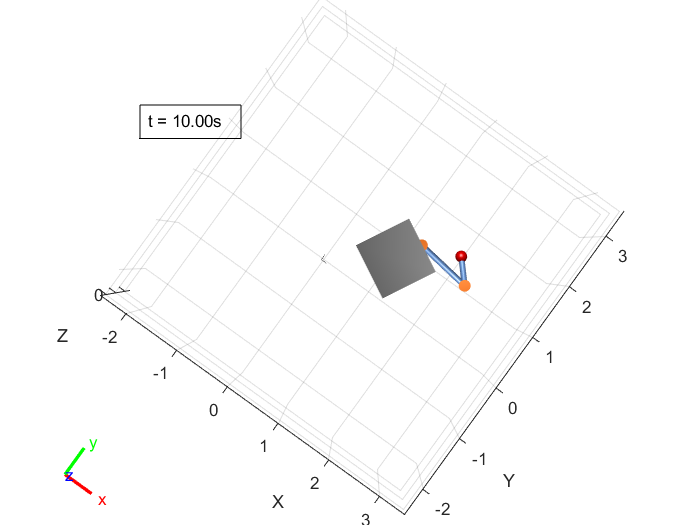

clc
close all
folder = 'Project/Videos/';

data = simRes.q.getsampleusingtime(0, animationTEnd);

if ~strcmp(fileName, '')
    savePath = strcat(folder, fileName);
else
    savePath = '';
end

tic
sc.animate(data, 'fps', 17, 'rate', 1, 'fileName', savePath); 

toc

Elapsed time is 11.433359 seconds.
